## Radar Transmit

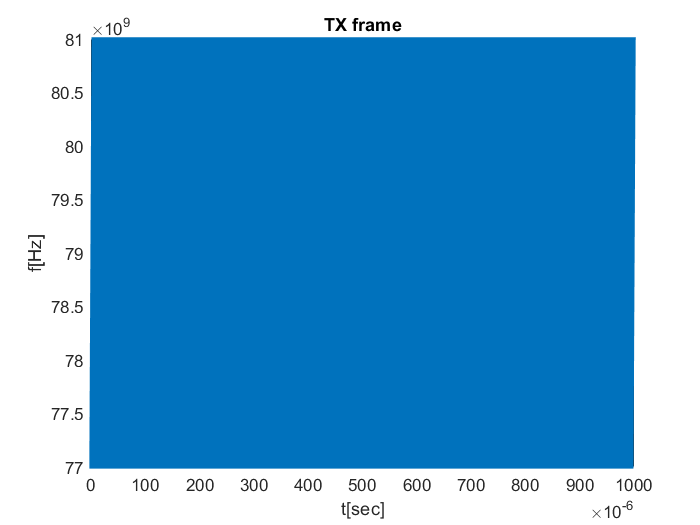

clear variables;
chirp_phi0 = 0;
chirp_f0_hz = 77e9;
chirp_bandwidth_hz = 4e9;
chirp_duration_sec = 4e-6; %40e-6; for speed up, reduce the chirp duration by a factor of 10, which will increase the difference tone.
Fs_adc_hz = 125e6; %12.5e6; As a result, increase the adc sampling rate by a factor of 10 in order to provide aliasing.
chirpyness = chirp_bandwidth_hz / chirp_duration_sec;
Fs_hz = (chirp_f0_hz + chirp_bandwidth_hz) * 4;
T_sec = 1/Fs_hz;
chirps_per_frame = 250;
frame_duration_sec = chirps_per_frame * chirp_duration_sec;
samples_per_chirp = round(chirp_duration_sec/T_sec);
samples_per_frame = samples_per_chirp * chirps_per_frame;
t_chirp_sec = linspace(0, chirp_duration_sec, samples_per_chirp)';
t_frame_sec = linspace(0, frame_duration_sec, samples_per_frame)';
tx_frame = repmat(cos(2*pi*(0.5 * chirpyness * t_chirp_sec.^2 + chirp_f0_hz * t_chirp_sec) + chirp_phi0), 1, chirps_per_frame);
plot(t_frame_sec, chirp_f0_hz + chirpyness * repmat(t_chirp_sec, chirps_per_frame, 1), '.');
title('TX frame'); xlabel('t[sec]'); ylabel('f[Hz]'); ax = gca; ax.YAxis.Exponent = 9; ax.XAxis.Exponent = -6;

## Targets

Here we can configure a vector of 1D targets.

targets_initial_position_m = [8 4];
target_velocity_mps = [3 1];
num_targets = numel(targets_initial_position_m);

## Radar Receive

For each target, an echo is received starting at a time delay of $\tau =\frac{2d}{c}$. Note that, we use a 'stop' approximation which means that the targets are static for the duration of the chirp and motion is taken into account only at inter chirps timing.

rx_frame = zeros(size(tx_frame));
figure; plot(t_frame_sec, chirp_f0_hz + chirpyness * repmat(t_chirp_sec, chirps_per_frame, 1), '.'); hold on;
color_order = get(gca, 'ColorOrder');
for chirp_idx = 1:chirps_per_frame
    for target_idx = 1:num_targets
        chirp_start_time_sec = (chirp_idx-1) * chirp_duration_sec;
        targets_position_m = targets_initial_position_m(target_idx) + target_velocity_mps(target_idx) * chirp_start_time_sec;
        target_delay_sec = 2 * targets_position_m / physconst('LightSpeed');
        rx_frame(round(target_delay_sec/T_sec):end, chirp_idx) = rx_frame(round(target_delay_sec/T_sec):end, chirp_idx) + tx_frame(1:(samples_per_chirp - round(target_delay_sec/T_sec) + 1), chirp_idx);
        t_shift_sec = (chirp_idx-1) * chirp_duration_sec;
        plot(t_chirp_sec + t_shift_sec , chirp_f0_hz + chirpyness * (t_chirp_sec - target_delay_sec), '.', 'Color', color_order(2 + mod(target_idx, size(color_order, 1) - 1), :));
    end
end
title('TX & RX frames'); xlabel('t[sec]'); ylabel('f[Hz]'); ylim([chirp_f0_hz, chirp_f0_hz + chirp_bandwidth_hz]);
hold off;

### Mixing and finding the difference tone before digitizing 

Since $\cos \left(2\pi f_1 \right)\cos \left(2\pi f_2 \right)=\cos \left(2\pi \left(f_1 +f_2 \right)\right)+\cos \left(2\pi \left(f_1 -f_2 \right)\right)$ and since the chirpyness is the same for the TX & RX, then for each sample the output of the mixer has two tones. One constant at $f_1 -f_2$ (this is an approximation, as there will also be a doppler shift during the chirp if the target moves) and another one which linearly varies at: $f_1 +f_2$. We are interested in the difference tone. It is proportional to the target distance from the radar. In order to extract it, we low pass filter the output of the mixer. Notice that we draw the plots with x limits which corresponds to the sampling rate of the digitizer. If the target is too far for the radar such that the difference frequency is higher than the $\frac{f_{s\_\textrm{adc}} }{2}$ and is not displayed here, then the range is ambigous as an alias of the peak will be digitized.

mixer_output = tx_frame .* rx_frame;  % Matlab throws a warning here, but it can ignored (execution continues normally).

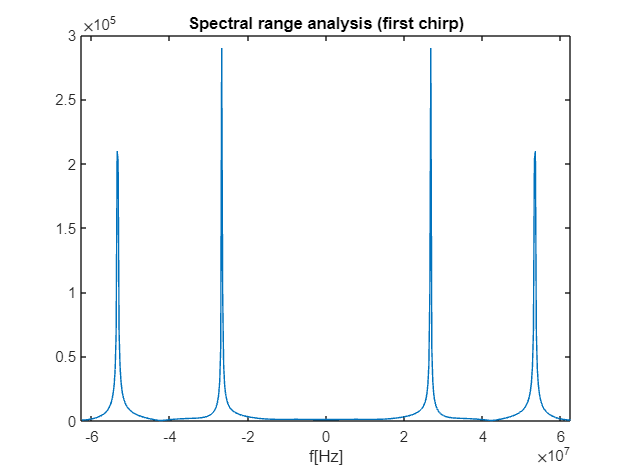

lpf = firls(255, [0, 0.25, 0.3, 1], [1, 1, 0, 0]);
mixer_output_diff = conv2(lpf, 1, mixer_output);
first_chirp_range_fft = fft(mixer_output_diff(:, 1));
plot(linspace(-Fs_hz/2, Fs_hz/2, length(first_chirp_range_fft)), abs(fftshift(first_chirp_range_fft))); xlim([-Fs_adc_hz/2, Fs_adc_hz/2]); xlabel('f[Hz]'); title('Spectral range analysis (first chirp)'); 

### Digitizing

This step affects the range resolution and the target maximum distance. Targets which are out of range will create aliases.

decimation_factor = round(Fs_hz/Fs_adc_hz);
mixer_output_diff_sampled = mixer_output_diff(1:decimation_factor:length(mixer_output_diff), :);

### Range FFT

Now that the return echos were digitized, we apply a range FFT and a detection algorithm. 

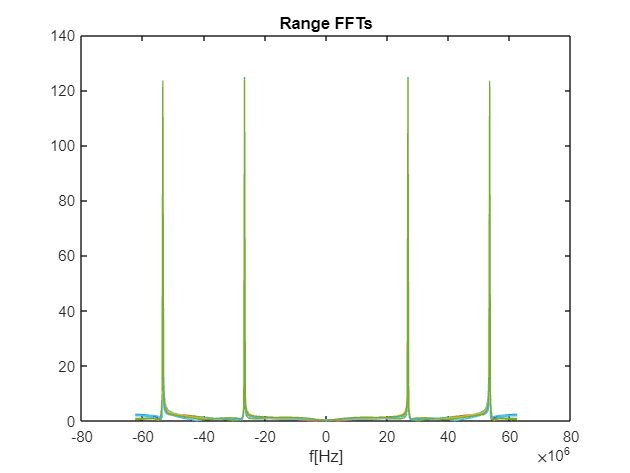

range_ffts = fft(mixer_output_diff_sampled, [], 1);
plot(linspace(-Fs_adc_hz/2, Fs_adc_hz/2, size(mixer_output_diff_sampled, 1)), abs(fftshift(range_ffts))); ax = gca; ax.XAxis.Exponent = 6; xlabel('f[Hz]'); title('Range FFTs');

### Detection and conversion to distance

In order to determine the distance to the detections, we use $d=\frac{f_{\textrm{if}} \cdot c}{2S}$, where $S$ is the chirpyness.

range_fft_res_hz = Fs_adc_hz/length(mixer_output_diff_sampled);
detections_ranges = zeros(num_targets, 1);
range_fft_1st_chirp = range_ffts(:, 1);
fft_len_post_decimation = length(range_fft_1st_chirp);
for target = 1:num_targets
    [~, detections_ranges(target)] = max(abs(range_fft_1st_chirp));
    f_d_hz = detections_ranges(target) * range_fft_res_hz;
    distance_m = f_d_hz * physconst('LightSpeed') / (2*chirpyness);
    fprintf('Distance to target%d is = %d[m]\n', target, distance_m)
    range_fft_1st_chirp(detections_ranges(target)) = 0;
    range_fft_1st_chirp(fft_len_post_decimation-detections_ranges(target)+1+1) = 0;
end

Distance to target1 is = 4.039120e+00[m]
Distance to target2 is = 8.040841e+00[m]


### Doppler FFT

We apply the doppler FFT to measure the velocity of the detected targets and seperate those which move at a different velocity but are equidistant from the radar. We only apply doppler FFTs in ranges where we had detections.

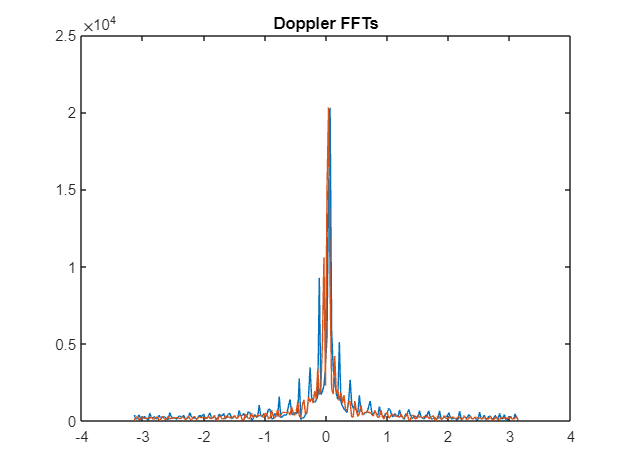

doppler_ffts = fft(range_ffts(detections_ranges ,:), [], 2);
Tcrp_sec = chirp_duration_sec;
plot(linspace(-pi, pi, size(doppler_ffts, 2)), abs(fftshift(doppler_ffts))); title('Doppler FFTs');

### Detection and conversion to velocity

In order to determine the velocity of the detections, we use $v=\frac{\omega }{4\pi T_c }\cdot \lambda$, where $T_c$ is the chirp repeatition period (in this case it is the chip duration).

The velocity resolution is given by $\frac{\lambda }{4MT_c }$, where $M$is the number of chips (bins in slow time).

lambda = physconst('LightSpeed')/chirp_f0_hz;
doppler_fft_anguler_res = (pi)/size(doppler_ffts, 2);
fprintf('Velocity resolution = %d[m/s]\n', (lambda/Tcrp_sec) * (doppler_fft_anguler_res/(4*pi)));

Velocity resolution = 9.733521e-01[m/s]


detections_velocities = zeros(num_targets, 1);
for target = 1:num_targets
    [~, detections_velocities(target)] = max(abs(doppler_ffts(target, :)));
    w_v_rps = detections_velocities(target) * doppler_fft_anguler_res;
    velocity_mps = (lambda/Tcrp_sec) * w_v_rps/(4*pi);
    fprintf('Target%d velocity is = %d[m/s]\n', target, velocity_mps);
end

Target1 velocity is = 1.946704e+00[m/s]
Target2 velocity is = 2.920056e+00[m/s]
